Rozważmy dwa układy dynamiczne:


$$G_{MP}=\frac{4s+1}{(s+1)^5}, G_{NMP}=\frac{-4s+1}{(s+1)^5} $$


den = [1 5 10 10 5 1];
lot = tf(1, den);
hot = tf([4 0], den);

sys_mp = lot + hot;
sys_nmp = lot - hot;

Są to układy różniące się tylko lokalizacją zer, ich charakterystyki Bodego i Nyquista wyglądaja następująco:

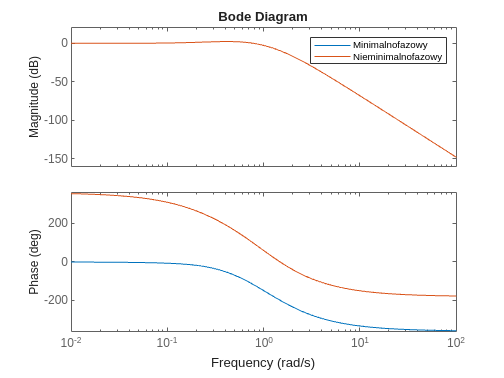

omega = logspace(-2, 2, 1000);
figure();
hold on;
grid on;
bode(sys_mp, omega);
bode(sys_nmp, omega);
legend("Minimalnofazowy", "Nieminimalnofazowy");

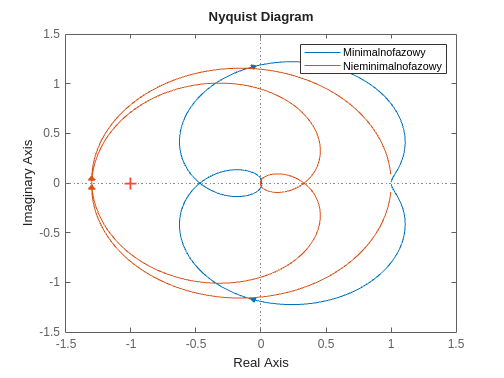


figure();
hold on;
grid on;
nyquist(sys_mp, omega);
nyquist(sys_nmp, omega);
legend("Minimalnofazowy", "Nieminimalnofazowy");

Odpowiedzi skokowe układów wyglądajają jak na wykresie poniżej. Charakterystyczną cechą układu nieminimalnofazowego jest to, że odpowiedź na wymuszenie skokowe idzie początkowo w przeciwnym kierunku do wymuszenia.

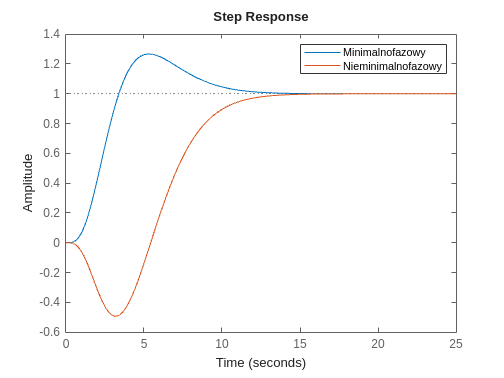

figure();
hold on;
grid on;
step(sys_mp);
step(sys_nmp);
legend("Minimalnofazowy", "Nieminimalnofazowy");

Jest tak ponieważ odpowiedź całego układu jest odpowiedzią na sume elementu inercyjnego $G_{MP}=\frac{1}{(s+1)^5}$ oraz elementu różniczkującego z inercją $G_{MP}=\frac{\pm 4s}{(s+1)^5}$

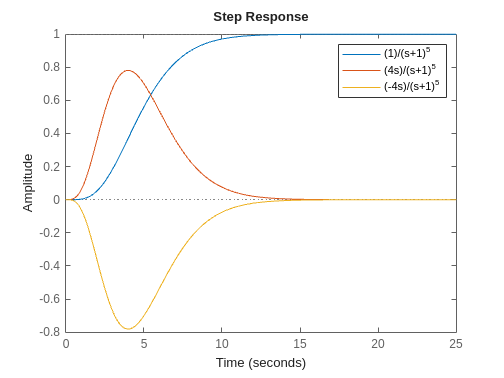

figure();
hold on;
grid on;
step(lot);
step(hot);
step(-hot);
legend("(1)/(s+1)^5", "(4s)/(s+1)^5", "(-4s)/(s+1)^5");

Jak zachowuje się z reguatorem proporcjonalnym? Im większe $K$ tym bardziej destabilizujemy.

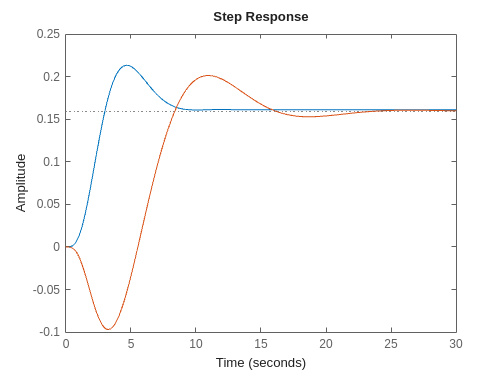

k = 0.19;

G_mp_cl = feedback(k * sys_mp, 1);
G_nmp_cl = feedback(k * sys_nmp, 1);

figure();
hold on;
step(G_mp_cl);
step(G_nmp_cl);